# 

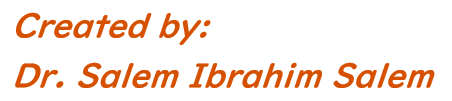

**Student Name(In English)**:Andreiev Maksym

**Student ID**:2022m666

# **Assignment No. (7)**

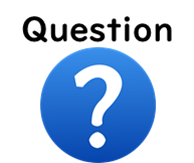

***Q1. *** The function $\textrm{"y"}$ can be defined as [$y=\left(0\ldotp 5x^4 +1\ldotp 1x^3 -0\ldotp 9x^2 \right)e^{-0\ldotp 7x}$] .

- plot (**x** versus **y**)  for $x$ ($-3\le x\le 10$)   ( use 50 elements between -3 & 10), considering the following formats 

              >  magenta dash-dot line with cross markers. 

              >  marker edge colors are black

              >  line width = 0.9

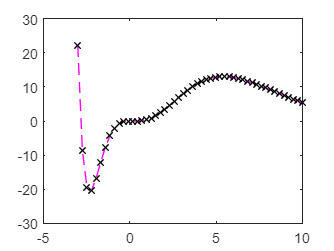

x = linspace(-3, 10, 50);
y = (0.5*x.^4 + 1.1*x.^3 - 0.9*x.^2) .* exp(-0.7*x);
plot(x, y, "m--x","LineWidth", 0.9, "MarkerEdgeColor", 'k')

***Q2. *** Plot the function [$y=x^2 e^{-x}$] and its derivative [$y_d =2xe^{-x} -x^2 e^{-x}$] for $x$ ($0\le x\le 10$) in the same figure, considering the following format:.

              >  The function "$y$" has solid line with circle markers

              >  The derivative "$y_d$" has dotted line with square marker. 

              >  line width = 2.2

              >  marker size is 7

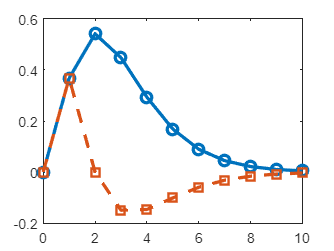

x = 0:10;
y = x.^2.*exp(-x);
yd = 2*x.*exp(-x) - x.^2.*exp(-x);
plot(x, y, '-o', x, yd, '--s', "LineWidth", 2.2, "MarkerSize", 7)

***Q3. *** The following table shows the monthly high and low temperature of Kyoto city. The temperature is shown in "fahrenheit". 

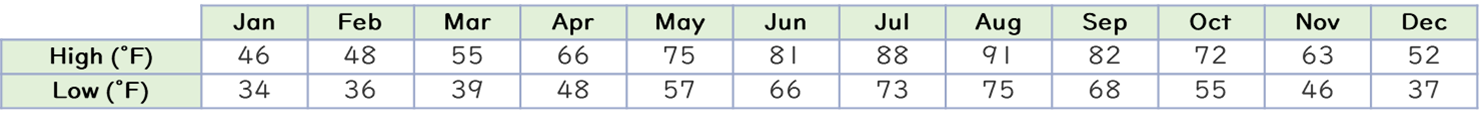

- Calculate the monthly mean temperature between high and low temperatures. 

- plot the monthly mean temperature versus months (i.e., months range is 1~12) considering the following formats

              >  **no line** and only asterisk markers 

              >  Marker Size = 8

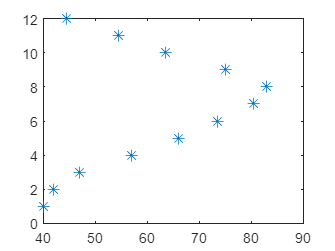

% define months
months = linspace(1, 12,12);   % months =  1:1:12  or  months =  1:12 >>> are also correct answers


% define the temperature in fahrenheit 
Temp = [46    48    55    66    75    81    88    91    82    72    63    52;
        34    36    39    48    57    66    73    75    68    55    46    37];


% Calculate the average temperature in celsius
m = mean(Temp);

% Plot
plot(m, months, '*', "MarkerSize", 8, "LineStyle","none")

***Q4.*** The following table shows the monthly precipitation for Kyoto city btween 2018 and 2020.

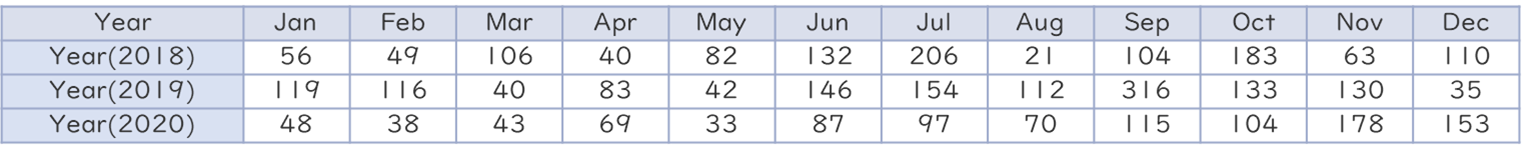

- Plot the monthly precipitation of the three years (i.e., 2018, 2019 & 2020) in the same figure considering the following format

              > Format of year(2018) > Blue solid line with square markers 

              > Format of year(2019) > Green dashed line with diamond markers 

              > Format of year(2020) > Black dotted line with asterisk markers 

              > Line width = 1.5

              > Marker size = 7.0

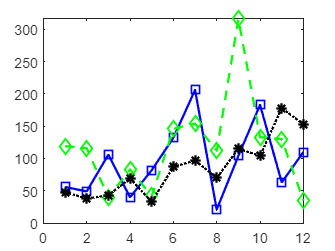

% define months
months = 1:1:12;   % months =  linspace(1, 12, 12)  OR  months =  1:12 >>> are also correct answers


Prec =[ 56    49   106    40    82   132   206    21   104   183    63   110;
       119   116    40    83    42   146   154   112   316   133   130    35;
        48    38    43    69    33    87    97    70   115   104   178   153];

% Plot monthly total precipitation of the three years

plot(months, Prec(1,:), 'b-s', months, ...
    Prec(2,:), 'g--d', months, Prec(3,:), ...
    'k:*', "LineWidth",1.5, "MarkerSize", 7)